# How to Run Simulink Simulation from MATLAB Script?

[ ](https://matlab.mathworks.com/open/github/v1?repo=simulink/blog&project=2024_06_25_sim/2024_06_25_sim.prj)

I recently ran into a report of the most visited entries on [MATLAB Answers](https://www.mathworks.com/matlabcentral/answers/index). I looked at the ones involving Simulink and thought it would be interesting to cover some of those on this blog. 

While most questions have direct answers, I think this is a good opportunity to provide additional background and cover some subtleties not addressed on MATLAB Answers.

This week, I am starting with the most visited:

- [how to run simulink simulation from matlab script](https://www.mathworks.com/matlabcentral/answers/330223-how-to-run-simulink-simulation-from-matlab-script)

Before giving you my answer to this question, I want to encourage you to visit the documentation page [Run Simulations Programmatically](https://www.mathworks.com/help/simulink/ug/using-the-sim-command.html). It covers in detail into all the options available and their implications.

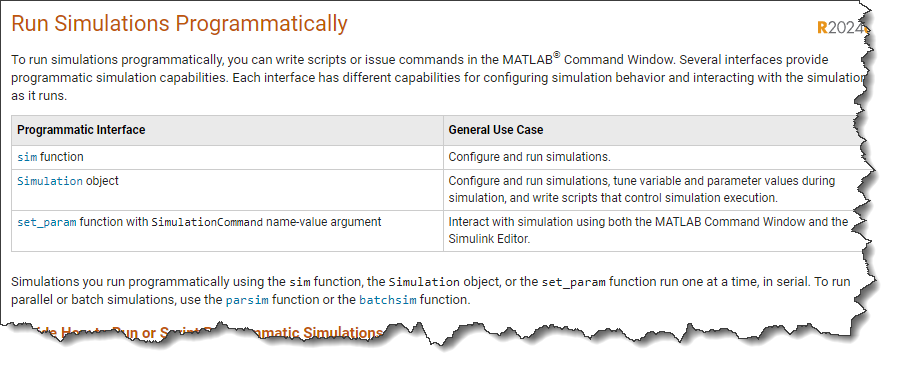

Now, let's go with my shorter informal version. 

To me, simulating a model programmatically boils down to the four following options:

- **Sim with model name:** Passing the model name to the [sim](https://www.mathworks.com/help/releases/R2024a/simulink/slref/sim.html) command. It's simple and works for many use cases.

- **Sim with Simulation Input object:** Passing a [Simulink.SimulationInput](https://www.mathworks.com/help/releases/R2024a/simulink/slref/simulink.simulationinput.html) object to the [sim](https://www.mathworks.com/help/releases/R2024a/simulink/slref/sim.html) command. The most versatile and scalable approach.

- **Simulation object:** Introduced in R2024a, the [Simulation](https://www.mathworks.com/help/releases/R2024a/simulink/slref/simulink.simulation.html) object provides an interface to control the simulation execution: start, step, stop and tune parameters.

- **Old and Discouraged: **Older syntaxes that are still available for backward compatibility, but that you should avoid.

## **Sim with Model Name**

If you have a Simulink model that simulates using the Run button, the quickest and simplest way to simulate it from MATLAB is probably to call the [sim](https://www.mathworks.com/help/releases/R2024a/simulink/slref/sim.html) command and pass it the model name.

For example, I have a model saved as `suspension.slx`.

mdl = 'suspension';
open_system(mdl)

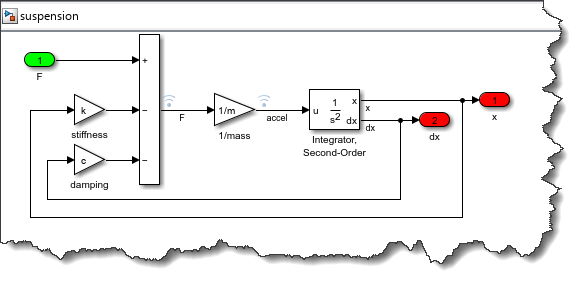

I can simulate it by first defining the data it needs in the MATLAB workspace and then calling sim:

out = sim(mdl)

out =   Simulink.SimulationOutput:

                logsout: [1x1 Simulink.SimulationData.Dataset] 
                   tout: [1003x1 double] 
                   yout: [1x1 Simulink.SimulationData.Dataset] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


All the logged data is contained within the variable `out`, which is a [Simulink.SimulationOutput](http://simulink.simulationoutputhttps//www.mathworks.com/help/releases/R2024a/simulink/slref/simulink.simulationoutput.html) object. For example, if I want to plot the velocity computed by the Integrator block, I can execute:

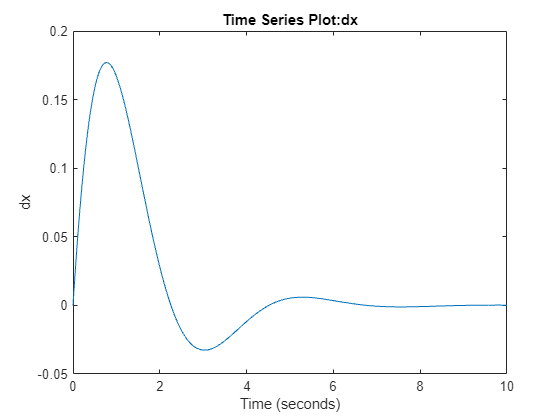

plot(out.yout.get('dx').Values)

If you try this with your model and sim returns a vector instead of a Simulation Output object, see the Old and Discouraged section below.

## **Sim with Simulation Input object**

While the above approach works in many cases, I recommend a slightly different approach. As described by [Reid Spence](https://www.mathworks.com/matlabcentral/profile/authors/12935569) in [this comment](https://www.mathworks.com/matlabcentral/answers/330223-how-to-run-simulink-simulation-from-matlab-script#answer_1394546), specifying a [Simulink.SimulationInput](https://www.mathworks.com/help/releases/R2024a/simulink/slref/simulink.simulationinput.html) object and passing it to the sim command offers a lot of advantages:

- Explicitly specify variables, signals, states and parameters used for the simulation.

- Straightforward transition to parallel simulations using [parsim](https://www.mathworks.com/help/releases/R2024a/simulink/slref/parsim.html), [batchsim](https://www.mathworks.com/help/releases/R2024a/simulink/slref/batchsim.html) and [Simulink Compiler](https://www.mathworks.com/products/simulink-compiler.html).

I expect that additional features to be released in future versions of Simulink will also be based on use of the Simulation Input object, so I encourage you to start using it today.

In its simplest form, using a Simulation Input object adds only one line of code to the previous approach:

in = Simulink.SimulationInput(mdl)

in =   SimulationInput with properties:

               ModelName: 'suspension'
            InitialState: [0×0 Simulink.op.ModelOperatingPoint]
           ExternalInput: []
         ModelParameters: [0×0 Simulink.Simulation.ModelParameter]
         BlockParameters: [0×0 Simulink.Simulation.BlockParameter]
               Variables: [0×0 Simulink.Simulation.Variable]
               PreSimFcn: []
              PostSimFcn: []
              UserString: ''
    VariantConfiguration: ''


You can then pass this to the sim command:

out = sim(in);

The main advantage of the Simulation Input object is that it explicitly specifies what is being passed to the sim function. For example, let's modify the previously created object by specifying:

- A different stop time:

in = in.setModelParameter('StopTime','20');

- A different value for the variable `k`:

in = in.setVariable('k',20);

- A signal for the root-level Inport block:

ds = createInputDataset(mdl);
ds{1} = timeseries([0 0 1 1],[0 10 10 20]);
in = in.setExternalInput(ds);

- The initial states of the Integrator block:

x0 = Simulink.BlockDiagram.getInitialState(mdl);
x0{1}.Values.Data(2) = 0.1;
in = in.setInitialState(x0);

I can then simulate the model and plot the results:

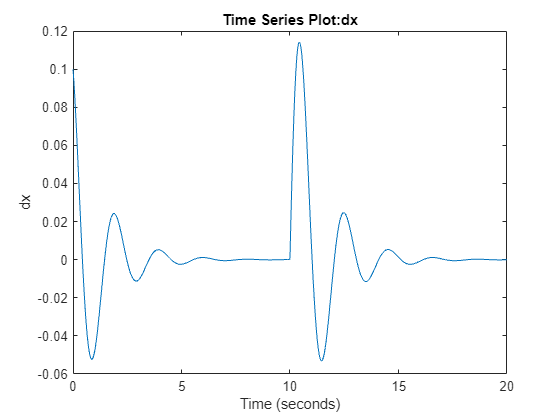

out = sim(in);
plot(out.yout.get('dx').Values)

## **Simulation object**

In R2024a, we introduced the [Simulation object](https://www.mathworks.com/help/releases/R2024a/simulink/slref/simulink.simulation.html). This object allows you to programmatically start, pause, step and tune block parameters in the same way as you would do while interacting with the Simulink editor.

Here is an example that runs the simulation between 0 and 5 seconds with variable `c` set to 0, and then runs it between 5 and 10 seconds with `c` equal to 10:

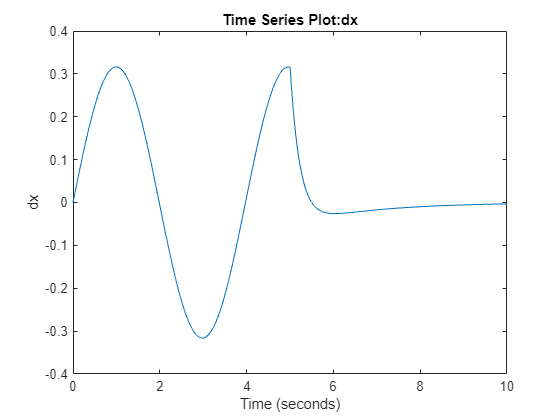

sm = simulation(mdl);
setVariable(sm,'c',0);
step(sm,PauseTime=5);
setVariable(sm,'c',10);
step(sm,PauseTime=10);
out = stop(sm);
plot(out.yout.get('dx').Values);

## **Old and Discouraged**

At this point, I need to cover approaches that we want to discourage. We are providing those for backward compatibility, but we discourage using them because they come with many limitations and usability issues. 

If you see one of those being used, I strongly encourage you to convert your code to use the Simulation Input object as described above.

In R2009b, we introduced the [Single simulation output](https://www.mathworks.com/help/releases/R2024a/simulink/gui/singlesimulationoutput.html) option.

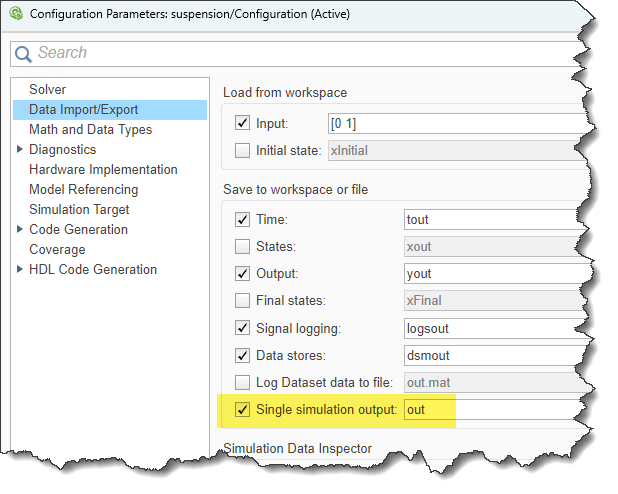

Programmatically, this option can be disabled using:

set_param(mdl,'ReturnWorkspaceOutputs','off');

Once this is done, you can call the sim command without output arguments:

sim(mdl)

Once the simulation complete, you will see the individual parameters specified in the Data Import/Export section of the configset magically appear in the MATLAB base workspace.

logsout

logsout = Simulink.SimulationData.Dataset 'logsout' with 2 elements

                         Name   BlockPath          
                         _____  __________________ 
    1  [1x1 Signal]      accel  suspension/1//mass
    2  [1x1 Signal]      F      suspension/Sum    

  - Use braces { } to access, modify, or add elements using index.


Another even older syntax that still exists only for backward incompatibility is this one, where the sim command returns 3 outputs for time, states, and outputs:

[t,x,y] = sim(mdl);

Once again, I recommend avoiding those and use the Simulation Input object instead.

## Other Considerations

### Running Multiple Simulations

If you are planning to run multiple simulations, I recommend creating an array of Simulation Input object and passing it to the sim command. Let's run our example for multiple damping values:

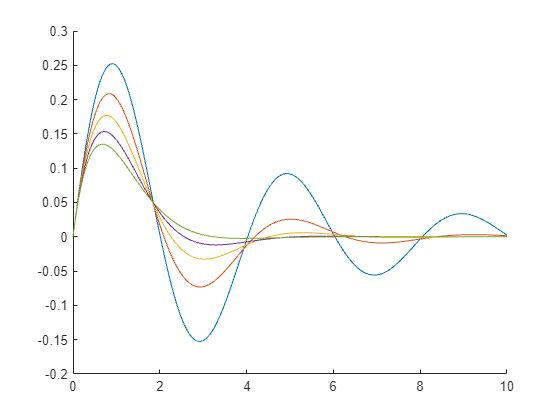

% Setup an array of SimulationInput objects
in(1:5) = Simulink.SimulationInput(mdl);
for i = 1:length(in)
    in(i) = in(i).setVariable('c',i);
end
% Simulating
out = sim(in,'ShowProgress','off');
% Visualizing results
figure;hold on
for i = 1:length(out)
    plot(out(i).yout.get('dx').Values);
end

To run this code in parallel, all you need to do is replace the call to sim with [parsim](https://www.mathworks.com/help/releases/R2024a/simulink/slref/parsim.html) or [batchsim](https://www.mathworks.com/help/releases/R2024a/simulink/slref/batchsim.html).

### Best Practice for Data Management

Simulations can be launched from multiple contexts: MATLAB Scripts, MATLAB Functions, MATLAB Classes, App Designer apps, etc. For your model to be easily run from any context, I recommend associating with your model a set of default values for all the parameters. This is typically done in two ways:

- [Model Workspace](https://www.mathworks.com/help/releases/R2024a/simulink/ug/using-model-workspaces.html)

- [Data Dictionary](https://www.mathworks.com/help/releases/R2024a/simulink/ug/what-is-a-data-dictionary.html) 

For more details on this topic, I recommend visiting: [Determine Where to Store Variables and Objects for Simulink Models](https://www.mathworks.com/help/releases/R2024a/simulink/ug/determine-where-to-store-data-for-simulink-models.html).

With that setup, it makes it easy to simply open the model and hit `Ctrl+D` to do an update diagram, or click Run to simulate it without the need to run any code. This also makes it easy to run functions like [Simulink.BlockDiagram.buildRapidAcceleratorTarget](https://www.mathworks.com/help/releases/R2024a/simulink/slref/simulink.blockdiagram.buildrapidacceleratortarget.html) or [slbuild](https://www.mathworks.com/help/releases/R2024a/simulink/slref/slbuild.html).

When times come to simulate the model, you can create Simulation Input objects to specify the data that needs to change from the default values associated with the model as illustrated above.

## Now it's your Turn

Have you adopted the Simulink.Simulation object? What's your preferred way to run simulations from MATLAB? Which challenges are you encountering when simulating models form MATLAB?

Let us know in the comments below.